Some visual intuition regarding the difference between batch and sequential approaches and why sequential approach can bring stochasticity, namely, we may occasionally go away from the expected gradient. 

First, let's make some data up. This is going to be a simple linear regression problem. Let's say that in my problem the true relationship between input (between 0 and 1) and the output is a linear relationship: y = a x + b where a and b are parameters of my choice. But because this is the real world, the y I will measure are not the exact y, they are noisy y. So I will add some random noise. 

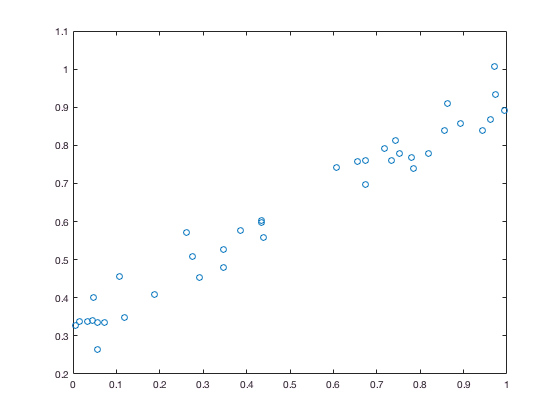

true_params=[0.6,0.35]; % the true parameters: y = 0.4x + 0.2
noise_param=0.04; % the world is noisy! 
x=rand(40,1); % training sample (randomly picked x values between 0 and 1)
y=true_params(1)*x+true_params(2)+noise_param*(randn(length(x),1)-0.5); % the observations
h1=figure(1); plot(x,y,'o'); hold on;

*NB: The larger noise_param, the more noisy the output. You can adjust the value if you like! *

Now, I am going to setup a Perceptron for regression. The output of my Perceptron will be: y = w1 x + w0 where w1 is the weight of the input (this is a 1D problem!) and w0 is the weight of the bias (set to 1 arbitrarily). I am now going to plot the error surface when I consider a simple quadratic error criterion (like mean square error). And because it's a simple problem, I'm going to plot it quite systematically (in a grid like manner). In real life, you would never do this of course! 

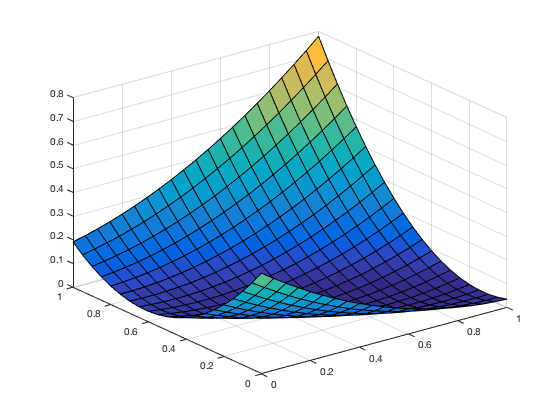

w0=0:0.05:1; % range of w0 considered
w1=0:0.05:1; % range of w1 considered
E=zeros(length(w0),length(w1)); % pre-allocate error values
for i=1:length(w0)
    for j=1:length(w1)
        delta=(y-(w1(j)*x+w0(i)));
        E(i,j)=delta'*delta/length(y);
    end
end
h2=figure(2); surf(w0,w1,E); hold on;

If you double-click on the figure, it will appear in a separate window and you can then rotate it in 3D to convince yourself it is a convex function.  It has a minimum which can find. 

[minw0idx,minw1idx]=find(E==min(min(E)));
fprintf('Minimum of error found at: %3.2f,%3.2f\n',w0(minw0idx),w1(minw1idx))

Minimum of error found at: 0.30,0.65


Depending on your initial conditions, amount of noise, resolution of your grid search, etc..., this may or may not be close to the true parameters. Anyhow, this is your error surface. 

Let's now consider what is happening when we do gradient descent. I am now going to assume I start from a randomly picked weight vector. Let's calculate the error associated with this vector and plot the point in the error landscape. 

wstart=rand(2,1)

wstart =     0.8316
    0.4378


%w=[0.25,0.45];
delta=(y-(wstart(1)*x+wstart(2)));
errorstart=delta'*delta/length(y)

errorstart = 0.0584

figure(2)
plot3(wstart(1),wstart(2),errorstart,'ro','Markersize',10,'MarkerFaceColor','red')
figure(1)
plot(x,wstart(1)*x+wstart(2),'m-');

This is where we can start getting a visual intuition for what is different between batch and stochastic. The error surface that are looking at is the result of looking at the mean square error over all of the points. The gradient of this error surface is therefore the gradient when all the points in the data are considered. We can do this analytically and we get:

gradient=-2/length(y)*[sum(delta.*x);sum(delta)]

gradient =     0.2701
    0.4537


which makes it possible to then identify the new weight (assuming a eta=0.1) 

wend=wstart-0.1*gradient 

wend =     0.8046
    0.3924


delta=(y-(wend(1)*x+wend(2)));
errorend=delta'*delta/length(y)

errorend = 0.0340

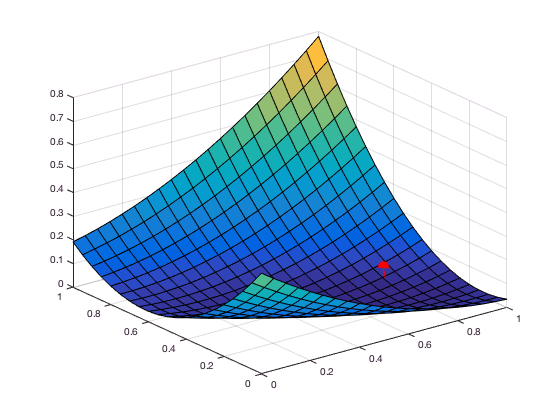

figure(2)
plot3([wstart(1),wend(1)],[wstart(2),wend(2)],[errorstart,errorend],'r-')

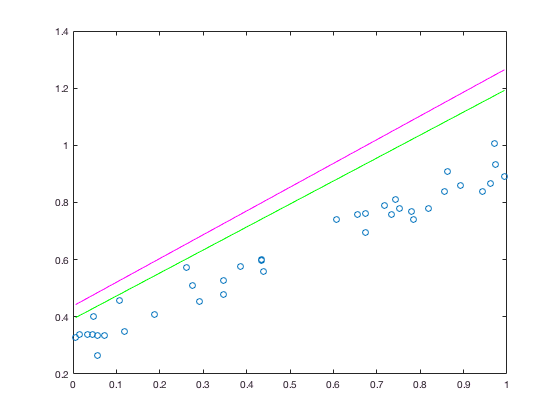

figure(1)
plot(x,wend(1)*x+wend(2),'g-');

Two things here: (a) the red line shows the gradient on the error surface. You can repeat this section many times if the red dot is not in a favourable place. (b) Look at the effect of the change in parameter on the new predictor (the green line should be a better fit than the purple line)

 So what happens when we use sequential gradient descent? Now the change in weights is no longer in relation to the sum over all data points (samples) but is done on a sample basis. This is the same as deciding how to update the two parameters based purely on the error we observe at the current sample. Let's now imagine that we are looking at a point which is currently below the predicted line but only because it is noisy. When we calculate the gradient for this point, the gradient will encourage the parameters to change to minimise that error. This may well make things worse. In the code below we evaluate the estimated gradient at each point and plot its coordinates with blue lines (showing in which direction it's pointing). Please note that I am not updating the weight so this is simply showing the different estimates. You should see quite a bit of dispersion including vectors pointing in opposite direction (which would be visual illustration that at a particular point, the gradient points in the 'wrong' direction). The red line corresponds to the 'batch' estimate. 

figure(3)
meangrad=[0;0];
for i=1:length(y)
    delta=y(i)-(w(1)*x(i)+w(2));
    gradient=-2*[delta*x(i);delta];
    meangrad=meangrad+gradient;
    line([0,gradient(1)],[0,gradient(2)]);
    hold on;
end
meangrad=meangrad/length(y);

meangrad =     0.0024
    0.0239


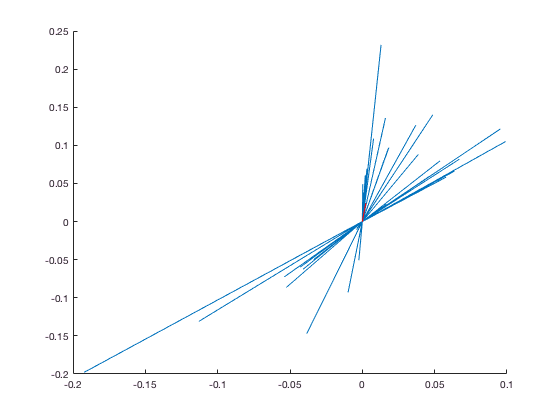

line([0,meangrad(1)],[0,meangrad(2)],'Color','r');

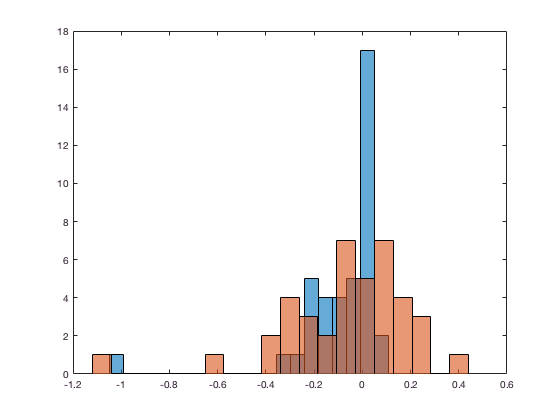

figure(4)
histogram(gradhist(:,1),20); hold on;
histogram(gradhist(:,2),20)

Let's compare speed now. Please note that the same number of gradients will have been calculated (100) but in batch we use 100 estimations for one update whereas in sequential we have 100 updates (one per gradient estimation). Compare the position of the green (batch) and red line (sequential).

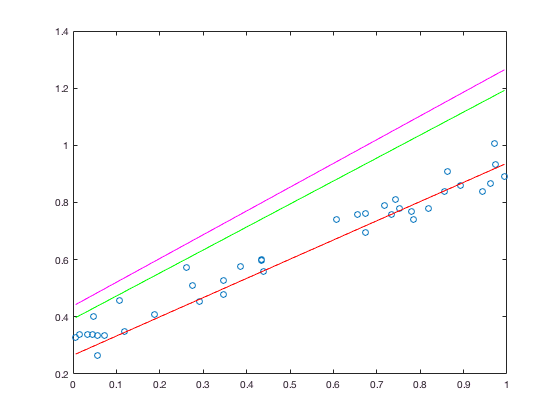

figure(5)
w=wstart; % current weight = starting weight
plot(x,y,'o'); hold on;
plot(x,w(1)*x+w(2),'m-');
plot(x,wend(1)*x+wend(2),'g-');
for i=1:length(y)
    delta=y(i)-(w(1)*x(i)+w(2));
    gradient=-2*[delta*x(i);delta];
    w=w-0.1*gradient;
    %input('Press Return')
end
plot(x,w(1)*x+w(2),'r-'); % my estimate after all data samples have been used once.